## Motor Speed Required

N = Gear Ratio

v = Max Speed

r = radius of the wheel

$\omega_m$= Motor Speed (rpm)


$$\omega_m =\frac{\textrm{Nv}}{2\pi r}$$


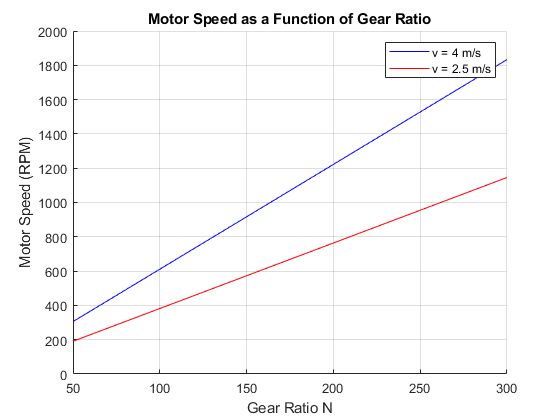


N = 50:50:300;
r = 1;
v1 = 4;
v2 = 2.5;
%w_m_values =[];
w_m_1 = N*v1*9.6/(2*pi*r);
w_m_2 = N*v2*9.6/(2*pi*r);
figure
hold on
plot(N,w_m_1,'blue')
hold on
plot(N,w_m_2,'red')

%xlim([0,300])
%ylim([0,1000])
hold off
legend('v = 4 m/s','v = 2.5 m/s')
xlabel('Gear Ratio N')
ylabel("Motor Speed (RPM)")
grid on
title('Motor Speed as a Function of Gear Ratio')

## Motor Torque Required


$$\begin{array}{l}
T_w =\textrm{Required}\;\textrm{Soil}\;\textrm{Thrust}\\
\eta_g =\textrm{Gear}\;\\
r=\textrm{radius}\;\textrm{of}\;\textrm{wheel}\\
N=\textrm{Gear}\;\textrm{ratio}\\
\tau_{m\;} =\textrm{Motor}\;\textrm{Torque}\\
\tau_{m\;} =\frac{T_w r}{\eta_g N}
\end{array}$$


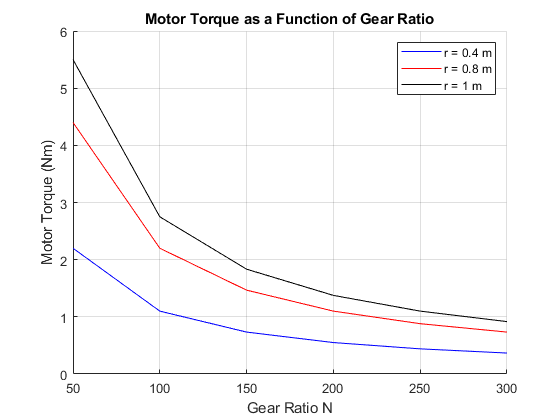

N = 50:50:300;
T_w = 550;
r1 = 0.4;
r2 = 0.8;
r3 = 1;
n_g = 2;
t_m_1 = (T_w*r1)*((N*n_g).^-1);
t_m_2 = (T_w*r2)*((N*n_g).^-1);
t_m_3 = (T_w*r3)*((N*n_g).^-1);
figure
hold on
plot(N,t_m_1,'blue')
hold on
plot(N,t_m_2,'red')
hold on 
plot(N,t_m_3,'black')
hold off
legend('r = 0.4 m','r = 0.8 m','r = 1 m')
xlabel('Gear Ratio N')
ylabel("Motor Torque (Nm)")
grid on
title('Motor Torque as a Function of Gear Ratio')

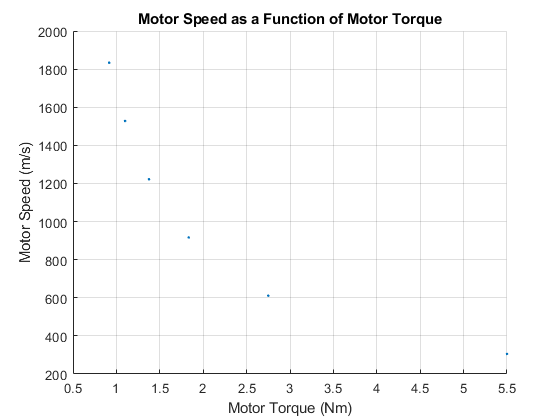



figure
%hold on
scatter(t_m_3,w_m_1,'.')
xlabel('Motor Torque (Nm)')
ylabel("Motor Speed (m/s)")
grid on
title('Motor Speed as a Function of Motor Torque')